clear;clc;

c = 299792.458;  %Km/s
miu_0 = 4e-7*pi;
m_p = 1.672621637e-27;  %Kg
kb = 8.617333262e-5; %ev/K

## 读取SolO的数据

% separate files
% magCdfFile1 = 'Data\SolO\solo_l2s_mag-rtn_20220119000000_20220831230837.cdf';
% magCdfFile2 = 'Data\SolO\solo_l2s_mag-rtn_20220901000000_20230427225742.cdf';
% magCdfInfo = spdfcdfinfo(magCdfFile1);
% magCdfVariables = magCdfInfo.Variables(:,1);
% magCdfData1 = spdfcdfread(magCdfFile1);
% magCdfData2 = spdfcdfread(magCdfFile2);
% magEpoch1 = magCdfData1{strcmp(magCdfVariables,'EPOCH')};
% magEpoch2 = magCdfData2{strcmp(magCdfVariables,'EPOCH')};
% magEpoch = [magEpoch1;magEpoch2];
% magB_RTN1 = magCdfData1{strcmp(magCdfVariables,'B_RTN')};
% magB_RTN2 = magCdfData2{strcmp(magCdfVariables,'B_RTN')};
% magB_RTN = [magB_RTN1;magB_RTN2];
%one file
magCdfFile = 'Data\SolO\solo_l2s_mag-rtn_20220119000000_20220831230837.cdf';
magCdfInfo = spdfcdfinfo(magCdfFile);
magCdfVariables = magCdfInfo.Variables(:,1);
magCdfData = spdfcdfread(magCdfFile);
magEpoch = magCdfData{strcmp(magCdfVariables,'EPOCH')};
magB_RTN = magCdfData{strcmp(magCdfVariables,'B_RTN')};

protonCdfFile = 'Data\SolO\solo_l2s_swa-pas-grnd-mom_20220119000003_20220119081815.cdf';
protonCdfInfo = spdfcdfinfo(protonCdfFile);
protonCdfVariables = protonCdfInfo.Variables(:,1);
protonCdfData = spdfcdfread(protonCdfFile);
protonEpoch = protonCdfData{strcmp(protonCdfVariables,'Epoch')};
protonV_RTN = protonCdfData{strcmp(protonCdfVariables,'V_RTN')};
protonN = protonCdfData{strcmp(protonCdfVariables,'N')};
% protonT = protonCdfData{strcmp(protonCdfVariables,'T')};
while sum(diff(protonEpoch)<=0)~=0
    [~,sortperm] = sort(protonEpoch);
    protonEpoch = protonEpoch(sortperm);
    protonV_RTN = protonV_RTN(sortperm,:);
    protonN = protonN(sortperm);
    continuityPoints = logical([1;diff(protonEpoch)>0]);
    protonEpoch = protonEpoch(continuityPoints);
    protonV_RTN = protonV_RTN(continuityPoints,:);
    protonN = protonN(continuityPoints);
end
protonV_RTN_nanpoints = any(protonV_RTN<-1e5,2);
protonV_RTN(protonV_RTN_nanpoints,:) = nan;

omniCdfFile = 'Data\SolO\omni2_h0s_mrg1hr_20220119003000_20220627003000.cdf';
omniCdfInfo = spdfcdfinfo(omniCdfFile);
omniCdfVariables = omniCdfInfo.Variables(:,1);
omniCdfData = spdfcdfread(omniCdfFile);
omniEpoch = omniCdfData{strcmp(omniCdfVariables,'Epoch')};
omniSSN = omniCdfData{strcmp(omniCdfVariables,'R')};
omniF107 = omniCdfData{strcmp(omniCdfVariables,'F10_INDEX')};

mergeCdfFile = 'Data\SolO\solo_coho1hrs_merged_mag_plasma_20220119000000_20220627000000.cdf';
mergeCdfInfo = spdfcdfinfo(mergeCdfFile);
mergeCdfVariables = mergeCdfInfo.Variables(:,1);
mergeCdfData = spdfcdfread(mergeCdfFile);
mergeEpoch = mergeCdfData{strcmp(mergeCdfVariables,'Epoch')};
mergeB = mergeCdfData{strcmp(mergeCdfVariables,'B')};
mergeV = mergeCdfData{strcmp(mergeCdfVariables,'ProtonSpeed')};
mergeN = mergeCdfData{strcmp(mergeCdfVariables,'protonDensity')};
mergeT = mergeCdfData{strcmp(mergeCdfVariables,'protonTemp')}; % K
mergeB(mergeB<0) = nan;
mergeV(mergeV<0) = nan;
mergeN(mergeN<0) = nan;
mergeT(mergeT<0) = nan;

mergeDateTime = datetime(mergeEpoch,"ConvertFrom","datenum");

posCdfFile = 'Data\SolO\solo_helio1days_position_20220118000000_20220628000000.cdf';
posCdfInfo = spdfcdfinfo(posCdfFile);
posCdfVariables = posCdfInfo.Variables(:,1);
posCdfData = spdfcdfread(posCdfFile);
posEpoch = posCdfData{strcmp(posCdfVariables,'Epoch')};
posR_AU = posCdfData{strcmp(posCdfVariables,'RAD_AU')};


## 利用质子、磁场原始数据，计算merge数据时间上的dVrms、dbrms;质子数据插值到磁场数据的时间点，并计算merge数据时间点上的σc

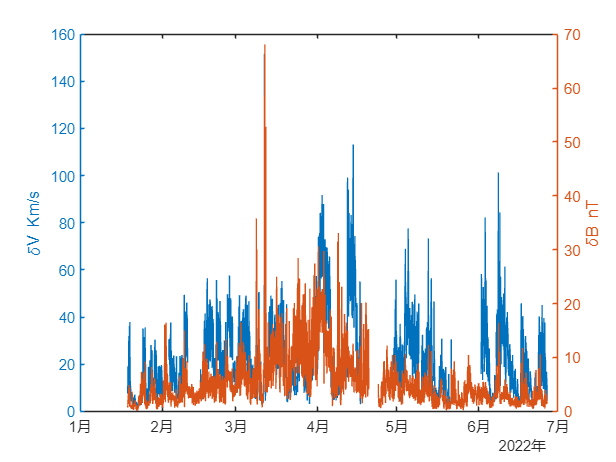

protonV_RTN_toMag = interp1(protonEpoch(~protonV_RTN_nanpoints),protonV_RTN(~protonV_RTN_nanpoints,:),magEpoch);
protonN_toMag = interp1(protonEpoch,protonN,magEpoch);

mergeEpochLength = length(mergeEpoch);

dBrms = NaN(mergeEpochLength,1);
dVrms = NaN(mergeEpochLength,1);
sigmaC = NaN(mergeEpochLength,1); % m * (x y z)

% dataResolution = dataResolutions(j); %s

for i = 1:mergeEpochLength    %单位是天
    theEpoch = mergeEpoch(i);

    theLogicTime = magEpoch>(theEpoch-1/48) & ...
        magEpoch<(theEpoch+1/48);
    if sum(theLogicTime)==0
        continue
    end
%     the_magEpoch = magEpoch(theLogicTime);
    the_magB_RTN = magB_RTN(theLogicTime,:);
    the_protonV_RTN_toMag = protonV_RTN_toMag(theLogicTime,:);
    the_protonN_toMag = protonN_toMag(theLogicTime);
    the_VA = 1e-15*the_magB_RTN./sqrt(miu_0*m_p*the_protonN_toMag);
    the_avg_protonV_RTN = mean(the_protonV_RTN_toMag,1,'omitnan');
    the_avg_VA = mean(the_VA,1,'omitnan');
    dBrms(i) = sqrt(sum(var(the_magB_RTN,1,1,'omitnan')));

    sigmaC(i) = 2*abs( mean( sum( (the_protonV_RTN_toMag-the_avg_protonV_RTN).*(the_VA-the_avg_VA) ,2,'omitnan') ,'omitnan') ...
        /(mean( sum( (the_protonV_RTN_toMag-the_avg_protonV_RTN).*(the_protonV_RTN_toMag-the_avg_protonV_RTN) ,2,'omitnan') ,'omitnan') ...
        + mean( sum( (the_VA-the_avg_VA).*(the_VA-the_avg_VA) ,2,'omitnan') ,'omitnan')));
end

for i = 1:mergeEpochLength    %单位是天
    theEpoch = mergeEpoch(i);

    theLogicTime = protonEpoch>(theEpoch-1/48) & ...
        protonEpoch<(theEpoch+1/48);
    if sum(theLogicTime)==0
        continue
    end
%     the_protonEpoch = protonEpoch(theLogicTime);
    the_protonV_RTN = protonV_RTN(theLogicTime,:);
    dVrms(i) = sqrt(sum(var(the_protonV_RTN,1,1,'omitnan')));
end

figure
yyaxis("left")
plot(mergeDateTime,dVrms)
ylabel("\deltaV Km/s")
hold on
yyaxis("right")
plot(mergeDateTime,dBrms)
ylabel("\deltaB nT")

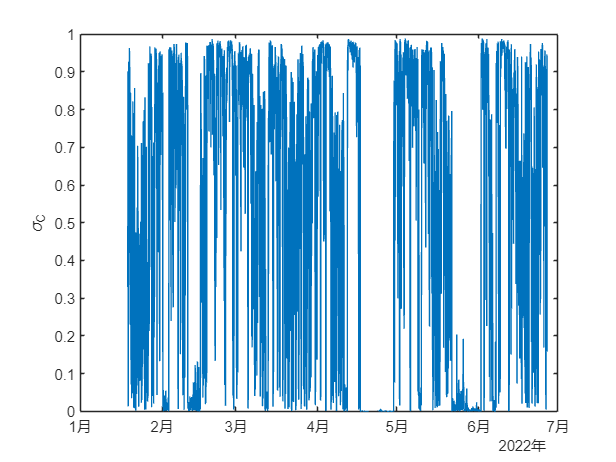


figure
plot(mergeDateTime,sigmaC)
ylabel("\sigma_C")

## 根据r 调整B、n、db2、dv2

posR_AU_toMag = interp1(posEpoch,posR_AU,magEpoch);
posR_AU_toProton = interp1(posEpoch,posR_AU,protonEpoch);
posR_AU_toMerge = interp1(posEpoch,posR_AU,mergeEpoch);

% magB_RTN(:,1) = magB_RTN(:,1).*(posR_AU_toMag.^2);
% magB_RTN(:,[2,3]) = magB_RTN(:,[2,3]).*posR_AU_toMag;
magB_RTN = magB_RTN.*(posR_AU_toMag.^2);
protonN = protonN.*(posR_AU_toProton.^2);
mergeB = mergeB.*(posR_AU_toMerge.^2);
mergeN = mergeN.*(posR_AU_toMerge.^2);
dBrms = dBrms.*(posR_AU_toMerge.^(3/2)); % Tu&Marsch 1995
dVrms = dVrms.*(posR_AU_toMerge.^(1/2)); % Tu&Marsch 1995

## 把SSN和F107插值到merge数据时间上，并生成测试数据

ssn = interp1(omniEpoch,single(omniSSN),mergeEpoch);
f107 = interp1(omniEpoch,omniF107,mergeEpoch);
% magB = sqrt(sum(magB_RTN.^2,2));
% magB_toMerge = interp1(magEpoch,magB,mergeEpoch);

theNaNIndexs = isnan(sigmaC) | isnan(dVrms) | isnan(dBrms) | isnan(mergeB) | isnan(mergeV) | isnan(mergeN) | isnan(mergeT);

sigmaC = sigmaC(~theNaNIndexs);
dBrms = dBrms(~theNaNIndexs);
dVrms = dVrms(~theNaNIndexs);
mergeB = mergeB(~theNaNIndexs);
% magB_toMerge = magB_toMerge(~theNaNIndexs);
mergeV = mergeV(~theNaNIndexs);
mergeT = mergeT(~theNaNIndexs);
Vthp = sqrt(kb*mergeT/938)*c*1e-3; %Km/s(要理解质量单位是eV/C2)
mergeN = mergeN(~theNaNIndexs);
datetimenum = mergeEpoch(~theNaNIndexs);
ssn = ssn(~theNaNIndexs);
f107 = f107(~theNaNIndexs);

DATA = [mergeB dBrms mergeV dVrms sigmaC Vthp mergeN ssn f107 datetimenum];
save evalSolOData_modified.mat DATA


## 读取Julia程序生成的模型结果，并和实际观测比较

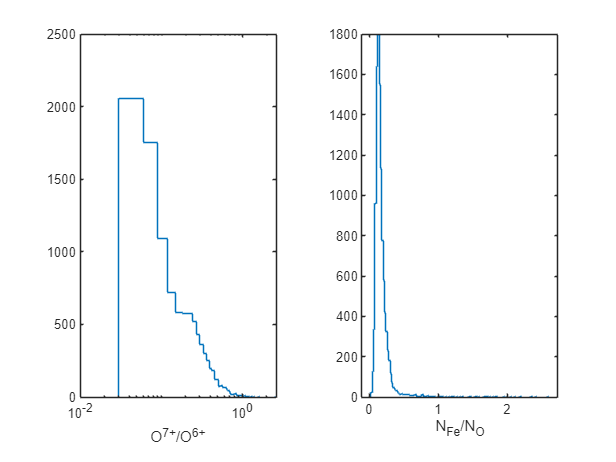

% clear;clc;
load Data\SolO\SolOY_modified.mat
Y = YData(1:6,:);
X = YData(7:15,:);
datetimeNum = YData(end,:);
datetimeSol = datetime(datetimeNum,"ConvertFrom","datenum");

nx = size(X,1);
ny = size(Y,1);

inputDataNames = ["B_{1AU} nT" "N_{p1AU} cm^{-3}" "Vp Km/s" "Vthp Km/s" "\deltaBrms nT" "\deltaVrms Km/s" "\sigma_C" "ssn" "F10.7"];
outputDataNames = ["Fe/O" "O7/O6" "C6/C5" "C6/C4" "N_{\alpha1AU} cm^{-3}" "V\alpha Km/s"];



hiCdfFile = 'Data\SolO\solo_l3s_swa-his-comp-10min_20220119000020_20220626093302.cdf';
hiCdfInfo = spdfcdfinfo(hiCdfFile);
hiCdfVariables = hiCdfInfo.Variables(:,1);
hiCdfData = spdfcdfread(hiCdfFile);
hiEpoch = hiCdfData{strcmp(hiCdfVariables,'EPOCH')};
hiVHe = hiCdfData{strcmp(hiCdfVariables,'HE2_SPEED')};
hiNHe = hiCdfData{strcmp(hiCdfVariables,'HE2_DENS')};
hiO76 = hiCdfData{strcmp(hiCdfVariables,'O7_O6_RATIO')};
hiC64 = hiCdfData{strcmp(hiCdfVariables,'C6_C4_RATIO')};
hiC65 = hiCdfData{strcmp(hiCdfVariables,'C6_C5_RATIO')};
hiFeO = hiCdfData{strcmp(hiCdfVariables,'FE_O_ABUN')};
hiVHe(hiVHe<0) = nan;
hiNHe(hiNHe<0) = nan;
hiO76(hiO76<0) = nan;
hiC64(hiC64<0) = nan;
hiC65(hiC65<0) = nan;
hiFeO(hiFeO<0) = nan;
hiDatetime = datetime(hiEpoch,"ConvertFrom","datenum");
hiY = [hiFeO hiO76 hiC65 hiC64]';
%应该筛选一下datetimeNum附近比较近的地方有数据的，否则不要
datetimeNum_near1 = datetimeNum-1/24;
datetimeNum_near2 = datetimeNum+1/24;
hi_datetime_flag = zeros(length(datetimeNum),1,'logical');
for i=1:length(datetimeNum)
    if sum((hiEpoch>=datetimeNum_near1(i))&(hiEpoch<datetimeNum_near2(i)))>0
        hi_datetime_flag(i)=true;
    end
end
hiY_tomerge = interp1(hiEpoch,hiY',datetimeNum(hi_datetime_flag))';

% pasCdfFile = 'Data\SolO\output-pas_mommag_np_pas_mommag_na_pas_mommag_va_0_1_2_pas_mommag_va_tot_pas_mo_2022000000000000.cdf';
% pasCdfInfo = spdfcdfinfo(pasCdfFile);
% pasCdfVariables = pasCdfInfo.Variables(:,1);
% pasCdfData = spdfcdfread(pasCdfFile);
% pasEpoch = pasCdfData{strcmp(pasCdfVariables,'AMDA_TIME')};
% pasVa = pasCdfData{strcmp(pasCdfVariables,'pas_mommag_va_tot_17344467917945651177')};
% pasNa = pasCdfData{strcmp(pasCdfVariables,'so_pas_l3_46_mommag_Na_17344467917945651177')};


% breakpoint = find(diff(pasEpoch)<=0);
% p1 = 1:breakpoint;
% p2 = breakpoint+1:length(pasEpoch);
% pp2 = p2(pasEpoch(p2)>pasEpoch(breakpoint));
% theperm = [p1 pp2];
% pasEpoch = pasEpoch(theperm);
% pasVa = pasVa(theperm);
% pasNa = pasNa(theperm);
% pasDatetime = datetime(pasEpoch,"ConvertFrom","datenum");
% posR_AU_toPas = interp1(posEpoch,posR_AU,pasEpoch);
% pasNa = pasNa.*(posR_AU_toPas.^2);% 把实测的N换算到1AU
% pasY = [pasNa pasVa]';
% pasY_tomerge = interp1(pasEpoch,pasY',datetimeNum(hi_datetime_flag))';
% hiY_tomerge = [hiY_tomerge;pasY_tomerge];

%%%%%%%%%%%% SolO 数据分布检测 %%%%%%%%%%
figure
tiledlayout(1,2)
nexttile
histogram(hiO76,'DisplayStyle','stairs')
xscale('log')
xlabel("O^{7+}/O^{6+}")
nexttile
histogram(hiFeO,'DisplayStyle','stairs')
xlabel("N_{Fe}/N_{O}")

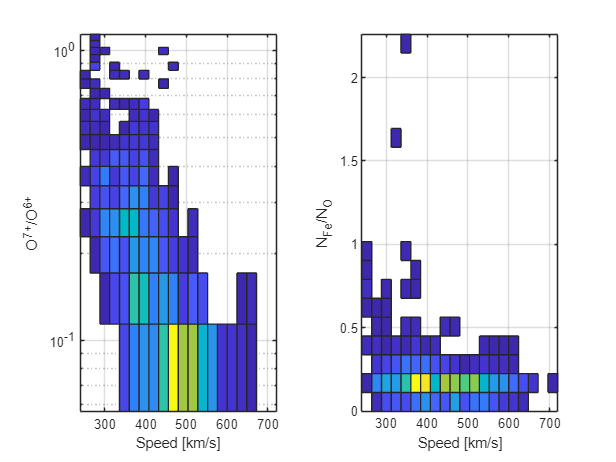


figure
tiledlayout(1,2)
nexttile
histogram2(X(3,hi_datetime_flag),hiY_tomerge(2,:),20,'DisplayStyle','tile')
yscale('log')
xlabel("Speed [km/s]")
ylabel("O^{7+}/O^{6+}")
nexttile
histogram2(X(3,hi_datetime_flag),hiY_tomerge(1,:),20,'DisplayStyle','tile')
xlabel("Speed [km/s]")
ylabel("N_{Fe}/N_{O}")

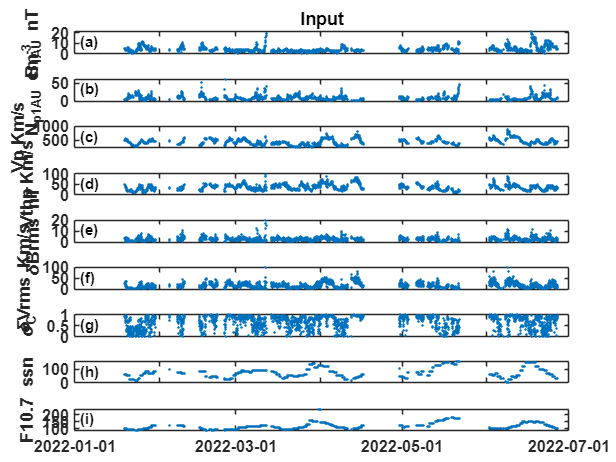


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% figure()
% for i=1:6
%     subplot(2,3,i)
%     scatter(hiY_tomerge(i,:),Y(i,hi_datetime_flag),3,"filled","MarkerFaceColor","blue")
%     theCC = corrcoef(hiY_tomerge(i,:),Y(i,hi_datetime_flag),'Rows','complete');
%     axis equal
%     title(outputDataNames(i))
%     xlabel("real");ylabel("model")
%     set(gca,'FontSize',15);
%     legend(sprintf("CC=%.2f",theCC(2)))
%     box on
% end


subplot_labels = ["(a)","(b)","(c)","(d)","(e)","(f)","(g)","(h)","(i)"];
subplot_id = 1;
% 
figure()
t = tiledlayout(nx,1);
for i=1:nx
    nexttile
    scatter(datetimeSol,X(i,:),3,"filled")
    if i==1
        title("Input",'FontSize',14,'FontWeight','bold')
    end
    if i~=nx
        set(gca,'xticklabel',[]);
    else
        xtickformat("yyyy-MM-dd")
    end
    ylabel(inputDataNames(i))
    
    set(gca,'FontSize',11,'FontWeight','bold');
    box on
    text(0.01,0.99,subplot_labels(subplot_id),Units="normalized", ...
        HorizontalAlignment="left",VerticalAlignment="top",FontWeight="bold")
    subplot_id = subplot_id+1;
end
t.TileSpacing = 'compact';
t.Padding = 'compact';

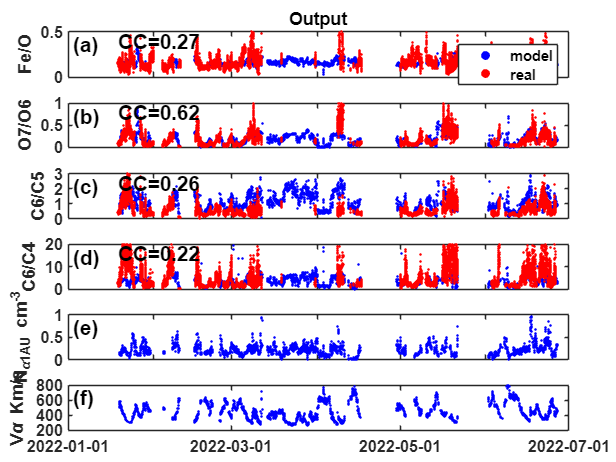


subplot_id = 1;
ylims1 = [0,0,0,0,0,200];
ylims2 = [0.5,1,3,20,1,800];
figure()
t = tiledlayout(ny,1);
for i=1:ny
    nexttile
    scatter(datetimeSol,Y(i,:),3,"filled","MarkerFaceColor","blue")
    ylim([ylims1(i) ylims2(i)])
    hold on
    if i<=4
        scatter(hiDatetime,hiY(i,:),3,"filled","MarkerFaceColor","red")
%     else
%         scatter(pasDatetime,pasY(i-4,:),3,"filled","MarkerFaceColor","red")
    end
    if i==1
        title("Output",'FontSize',14,'FontWeight','bold')
        legend("model","real")
    end
    if i~=ny
        set(gca,'xticklabel',[]);
    else
        xtickformat("yyyy-MM-dd")
    end
    if i<=4
        theCC = corrcoef(hiY_tomerge(i,:),Y(i,hi_datetime_flag),'Rows','complete');
        text('String',sprintf("CC=%.2f",theCC(2)),'Units','normalized','position',[0.1, 0.8],'FontSize',14,'FontWeight','bold')
    end
    ylabel(outputDataNames(i))
    set(gca,'FontSize',11,'FontWeight','bold');
%     if i==5
%         ylim([0,5])
%     end
    box on
    text(0.01,0.99,subplot_labels(subplot_id),Units="normalized", ...
        HorizontalAlignment="left",VerticalAlignment="top",FontWeight="bold",FontSize=14)
    subplot_id = subplot_id+1;
end
t.TileSpacing = 'compact';
t.Padding = 'compact';

% Na2Np = hiY_tomerge(5,:)./X(2,:);
% Na2Np_out = Y(5,:)./X(2,:);
% figure
% scatter(Na2Np,Na2Np_out,3,"filled","MarkerFaceColor","blue")
% theCC = corrcoef(Na2Np,Na2Np_out,'Rows','complete');
% axis equal
% title(outputDataNames(5))
% xlabel("real");ylabel("model")
% set(gca,'FontSize',15);
% legend(sprintf("CC=%.2f",theCC(2)))

## 如果只考虑r>0.8的部分

% posCdfFile = 'Data\SolO\solo_helio1days_position_20220118000000_20220628000000.cdf';
% posCdfInfo = spdfcdfinfo(posCdfFile);
% posCdfVariables = posCdfInfo.Variables(:,1);
% posCdfData = spdfcdfread(posCdfFile);
% posEpoch = posCdfData{strcmp(posCdfVariables,'Epoch')};
% posR_AU = posCdfData{strcmp(posCdfVariables,'RAD_AU')};
% posR_AU_toMerge = interp1(posEpoch,posR_AU,datetimeNum);
% 
% largeR_points = posR_AU_toMerge>0.8;
% 
% figure()
% for i=1:4
%     subplot(2,2,i)
%     scatter(hiY_tomerge(i,largeR_points),Y(i,largeR_points),3,"filled","MarkerFaceColor","blue")
%     theCC = corrcoef(hiY_tomerge(i,largeR_points),Y(i,largeR_points),'Rows','complete');
%     axis equal
%     title(outputDataNames(i))
%     xlabel("real");ylabel("model")
%     set(gca,'FontSize',15);
%     legend(sprintf("CC=%.2f",theCC(2)))
% end
% figure()
% for i=1:4
%     subplot(2,2,i)
%     scatter(hiY_tomerge(i,~largeR_points),Y(i,~largeR_points),3,"filled","MarkerFaceColor","blue")
%     theCC = corrcoef(hiY_tomerge(i,~largeR_points),Y(i,~largeR_points),'Rows','complete');
%     axis equal
%     title(outputDataNames(i))
%     xlabel("real");ylabel("model")
%     set(gca,'FontSize',15);
%     legend(sprintf("CC=%.2f",theCC(2)))
% end